Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |       11.67% |       28.11% |       4.1148 |       2.3240 |      1.0000e-04 |
|       1 |           5 |       00:00:39 |       30.00% |       52.43% |       1.8310 |       1.5390 |      1.0000e-04 |
|       1 |          10 |       00:01:10 |       50.00% |       76.76% |       1.4204 |       1.1401 |      1.0000e-04 |
|       2 |          15 |       00:01:40 |       75.00% |       81.08% |       0.8454 |   

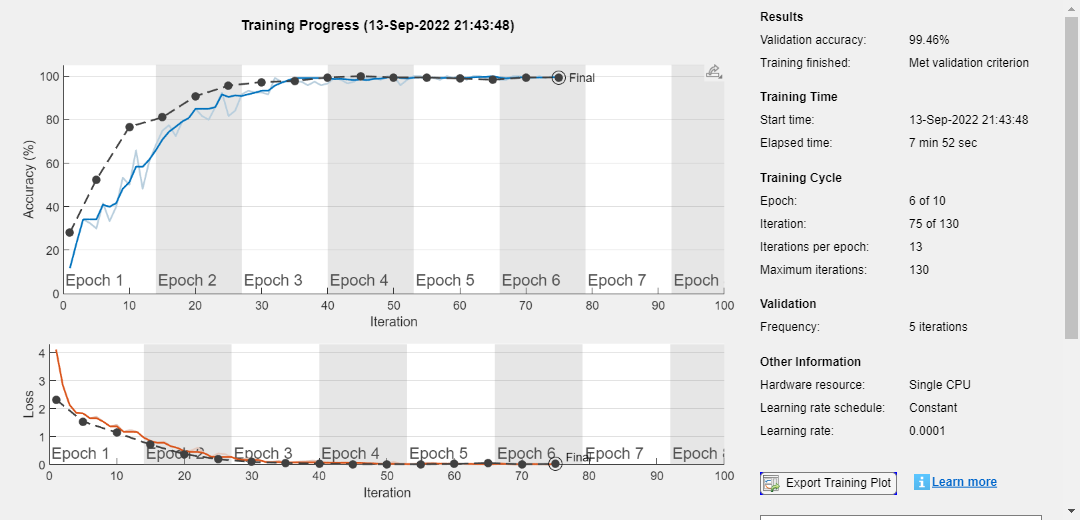

anet=alexnet;
 
alayersTransfer=anet.Layers(1:end-3);
clear anet;
anumClasses=numel(categories(imdsTrain.Labels));

alayers = [
    alayersTransfer
    fullyConnectedLayer(anumClasses,'Name', 'fc','WeightLearnRateFactor',1,'BiasLearnRateFactor',1)
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')];

aoptions=trainingOptions('adam', ...
    'MiniBatchSize',120, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',0.0001, ...
    'ValidationData',augmented_imdsValid, ...
    'ValidationFrequency',5,'ValidationPatience',4, ...
    'Plots','training-progress');

%Training
anetTransfer=trainNetwork(augmented_imdsTrain,alayers,aoptions);

 
%Testing
[apredicted_labels,apredicted_scores]=classify(anetTransfer,augmented_imdsTest);

aPerItemAccuracy = mean(apredicted_labels == actual_labels)

aPerItemAccuracy = 0.9913